依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

模板细胞的命中错失

GroupNtats=TransferLearning.QueryNTATS('Fig1L',TransferLearning.Flags.Different_cells_stripped);

[~,GroupNtats.PeakTime]=max(GroupNtats.NTATS,[],2);
[Mean,Sem]=MATLAB.DataFun.MeanSem(GroupNtats.NTATS{isbetween(GroupNtats.PeakTime.Learned-GroupNtats.PeakTime.Transfer_hit,-1,1)&isbetween(GroupNtats.PeakTime.Learned,25,32),:,["Transfer_hit","Transfer_miss"]},1);
Mean=permute(Mean,[2,3,1]);
Sem=permute(Sem,[2,3,1]);
Xs=linspace(-3,2,40).';

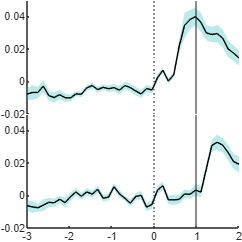

Fig=figure;
Layout=tiledlayout(2,1,TileSpacing='none',Padding='none');
Axes=gobjects(2,1);
for T=1:2
	Axes(T)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(Mean(:,T),Sem(:,T),0.3,X=Xs);
	xline(0,':');
	xline(1,'-');
end
Axes(1).XAxis.Visible='off';
MATLAB.Graphics.UnifyAxesLims(Axes,@ylim);
MATLAB.Graphics.FigureAspectRatio(1,1,1/2);
print(Fig,TransferLearning.ProjectPath('Fig1L.svg'),'-dsvg');